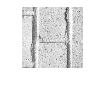

A = double(imread("media/texture_brick.tiff"));
A = A(1:256, 1:256);
imshow(A/255);

sigma = double(zeros(256,256));
sigma(randperm(numel(sigma), 45875)) = 1.0;
A1 = A.*sigma;
I_final_n = zeros(256,256);
I_final = double(zeros(256,256));
for i=4:253
    for j=4:253
        patch = A1(i-3:i+3,j-3:j+3);
        window = A1(max(1,i-10):min(256,i+10),max(1,j-10):min(256,j+10));
        sigm_wind = sigma(max(1,i-10):min(256,i+10),max(1,j-10):min(256,j+10));
        x_1 = i-3-max(1,i-10)+1;
        y_1 = j-3-max(1,j-10)+1;
        recover = SVT(window, sigm_wind, 10, min(256,i+10)-max(1,i-10)+1,min(256,j+10)-max(1,j-10)+1);
        rec_patch = recover(x_1:x_1+6,y_1:y_1+6);
        I_final(i-3:i+3,j-3:j+3) = I_final(i-3:i+3,j-3:j+3) + rec_patch;
        I_final_n(i-3:i+3,j-3:j+3) = I_final_n(i-3:i+3,j-3:j+3) +1;
    end
end
I_final = I_final./I_final_n;
I_final = round(I_final)

I_final =    227   222     2     1   202   220     4   220   211   200     3   206   221     3   204   216   221   216   210   213   220   209     3   202     3   195     3   204   193     4   190   206   212   202     2     1   197   190   205     2   228   204   210   210     6   199   182   106    95   111
   230   224   214   206   211   225   207   199   211     6   205   205   199   199   201   221   214     2     1   207     3   213   197   179   198   211   208     2   194   190     2     5   219   220   222     1   201   178   199     3   224   210     4   209   221   202   179   129    94     2
   221   219   219   216   214   207   172   161     6     2   202   206   200   203   192     2   211   205   205     2   185   212     3   179   191     2   216     3   196     1     1   204   221     2     2     1   211   206   202   218   211   203     1     4   212     2   176     2   107   114
     6   214   213   208   216   202     3   163   174   197   208   216   214   199   

rmse = norm(I_final-A,'fro')/norm(A,'fro')

rmse = 0.5419

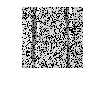

imshow(I_final/255);

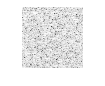

A = double(imread("media/textture_sand.tiff"));
A = A(1:256, 1:256);
imshow(A/255);

sigma = (zeros(256,256));
sigma(randperm(numel(sigma), 45875)) = 1;
A1 = A.*sigma;
I_final_n = zeros(256,256);
I_final = double(zeros(256,256));
for i=4:253
    for j=4:253
        patch = A1(i-3:i+3,j-3:j+3);
        window = A1(max(1,i-10):min(256,i+10),max(1,j-10):min(256,j+10));
        sigm_wind = sigma(max(1,i-10):min(256,i+10),max(1,j-10):min(256,j+10));
        x_1 = i-3-max(1,i-10)+1;
        y_1 = j-3-max(1,j-10)+1;
        recover = SVT(window, sigm_wind, 0.01, min(256,i+10)-max(1,i-10)+1,min(256,j+10)-max(1,j-10)+1);
        rec_patch = recover(x_1:x_1+6,y_1:y_1+6);
        I_final(i-3:i+3,j-3:j+3) = I_final(i-3:i+3,j-3:j+3) + rec_patch;
        I_final_n(i-3:i+3,j-3:j+3) = I_final_n(i-3:i+3,j-3:j+3) +1;
    end
end
I_final = I_final./I_final_n;
I_final = round(I_final)

I_final =      0   230     0     0   230     0     0   237   223     0   224   229   227     0   209   220   221   211     0   229   224   227     0   200   192   206     0     0   120   158     0   201   210   220   221     0   219     0   229     0     0   230   236     0   239   240   241   238   230   229
   240   241   246   251   250   240     0     0   229   225   221   204   210   217   217   216   219   219   227   226   214   197   204   212   218     0     0   230   194   191   212   200   168   194   211     0     0   227   234   237   232   236   242   242   242     0   231   231   234   238
   245   244     0   246     0     0   209   221   225     0     0   213   192     0   166   192   204   220   223   220   204   212   214   219     0     0   236   237     0   224     0   218   196   201   182   182     0     0   229     0   234     0   227     0   221   195     0   209   215   226
   251   254     0     0     0   236     0   222   228   232   237   231   211   136   

rmse = norm(I_final-A,'fro')/norm(A,'fro')

rmse = 0.5478

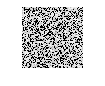

imshow(I_final/255);